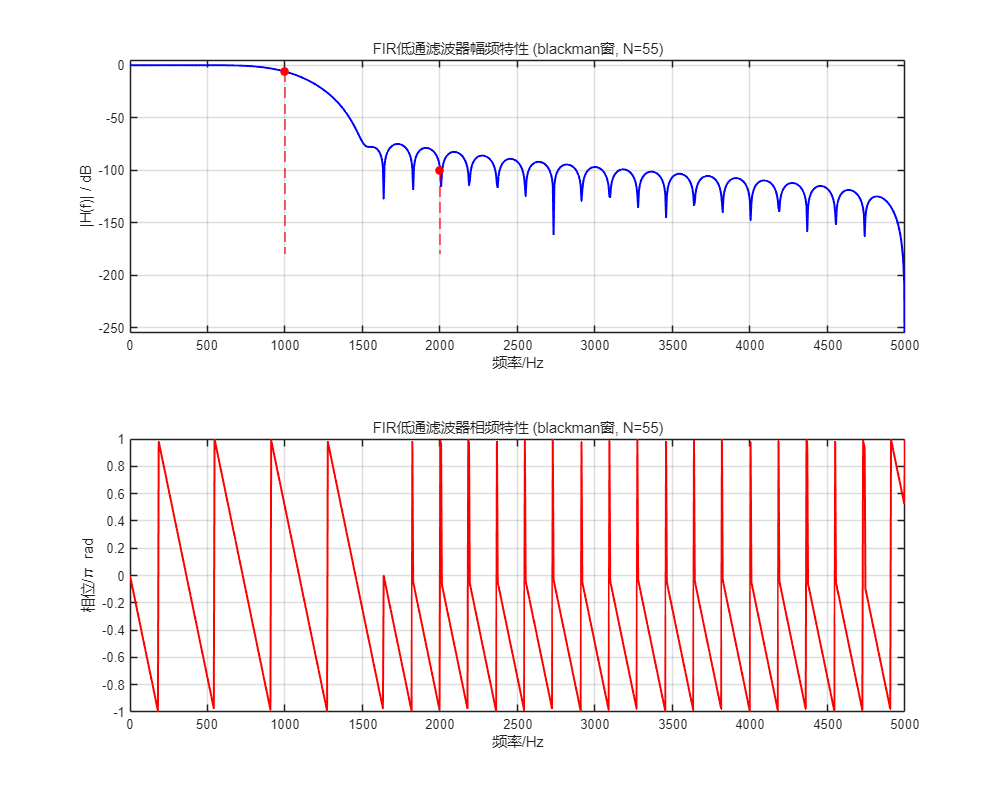

%% FIR数字低通滤波器设计 - 窗函数法
% 要求f_p=1kHz，δ_p≤6dB，f_s=2kHz，δ_s≥55dB，采样间隔T=0.1ms

fp = 1000;      % 通带截止频率(Hz)
fs = 2000;      % 阻带起始频率(Hz)
dp = 6;         % 通带衰减最大值(dB)
ds = 55;        % 阻带衰减最小值(dB)
T = 0.1/1000;   % 采样间隔0.1ms
fT = 1/T;       % 采样频率10kHz

% 计算数字频率
wp = 2*pi*fp*T;    % 数字通带角频率
ws = 2*pi*fs*T;    % 数字阻带角频率

% 计算过渡带宽
delta_w = ws - wp;  % 过渡带宽(rad)

% 使用布莱克曼窗
window_type = 'blackman';
N_blackman = ceil(11*pi/delta_w); % (delta_w = 11pi/N)

% 设计FIR滤波器
wc = wp; % 截止频率
b_blackman = fir1(N_blackman, wc/pi, 'low', blackman(N_blackman+1));

%% 布莱克曼窗设计的幅频和相频特性
figure('Position', [100, 100, 1000, 800]);

% 计算频率响应
w = linspace(0, pi, 1000);
[H_blackman, w_freq] = freqz(b_blackman, 1, w);
H_blackman_dB = 20*log10(abs(H_blackman));
f_Hz = w_freq/(2*pi*T); % 将数字频率转换为Hz

subplot(2,1,1);
plot(f_Hz, H_blackman_dB, 'b-', 'LineWidth', 1.5);
grid on;
title(sprintf('FIR低通滤波器幅频特性 (%s窗, N=%d)', window_type, N_blackman));
xlabel('频率/Hz');
ylabel('|H(f)| / dB');
axis([0, 5000, -150, 5]);

fp_index = find(f_Hz >= fp, 1);
fs_index = find(f_Hz >= fs, 1);
fp_magnitude_blackman = H_blackman_dB(fp_index);
fs_magnitude_blackman = H_blackman_dB(fs_index);
hold on;
plot([fp, fp], [fp_magnitude_blackman, -180], 'r--', 'LineWidth', 1);
plot([fs, fs], [fs_magnitude_blackman, -180], 'r--', 'LineWidth', 1);
plot(fp, fp_magnitude_blackman, 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'red');
plot(fs, fs_magnitude_blackman, 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'red');

% 相频特性曲线
subplot(2,1,2);
phase_blackman = angle(H_blackman); % 获取相位（弧度）
phase_blackman_pi = phase_blackman / pi; % 转换为π单位
plot(f_Hz, phase_blackman_pi, 'r-', 'LineWidth', 1.5);
grid on;
title(sprintf('FIR低通滤波器相频特性 (%s窗, N=%d)', window_type, N_blackman));
xlabel('频率/Hz');
ylabel('相位/\pi rad');
axis([0, 5000, -1, 1]); 